txWaveform

txWaveform = nrOFDMModulate(carrierCopy, txGridCopy);
fprintf("txWaveform")

txWaveform

fs = 7680000;
nfft = 256

nfft = 256

symLgths = [552   548   548   548   548   548   548   552   548   548   548   548   548   548]

symLgths =    552   548   548   548   548   548   548   552   548   548   548   548   548   548


s1 = symLgths(1);
s2 = symLgths(1) + symLgths(2);
s3 = symLgths(1) + symLgths(2) + symLgths(3);
s4 = symLgths(1) + symLgths(2) + symLgths(3) + symLgths(4)

s4 = 2196

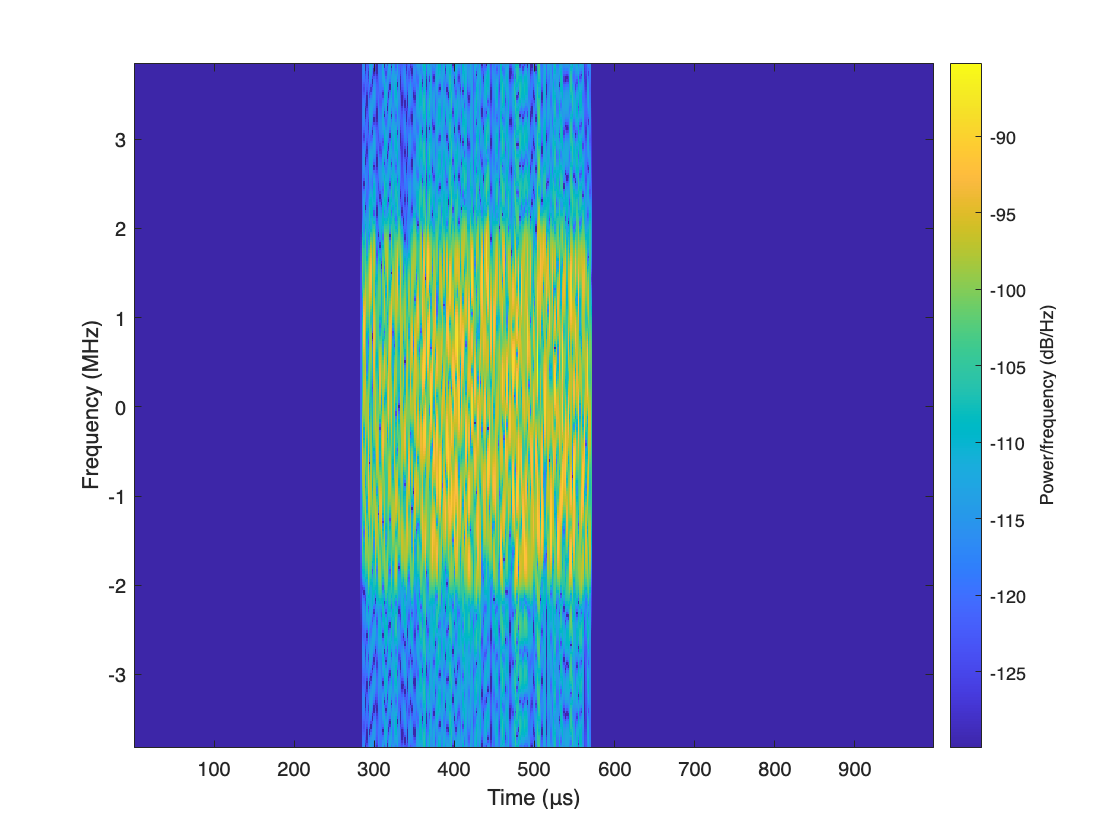


spectrogram(txWaveform,symLgths,0,nfft,'centered',7680000,'yaxis','MinThreshold',-130);


% spectrogram(txWaveform,Nfft,0,Nfft,'centered',76800,'yaxis','MinThreshold',-130)


radar

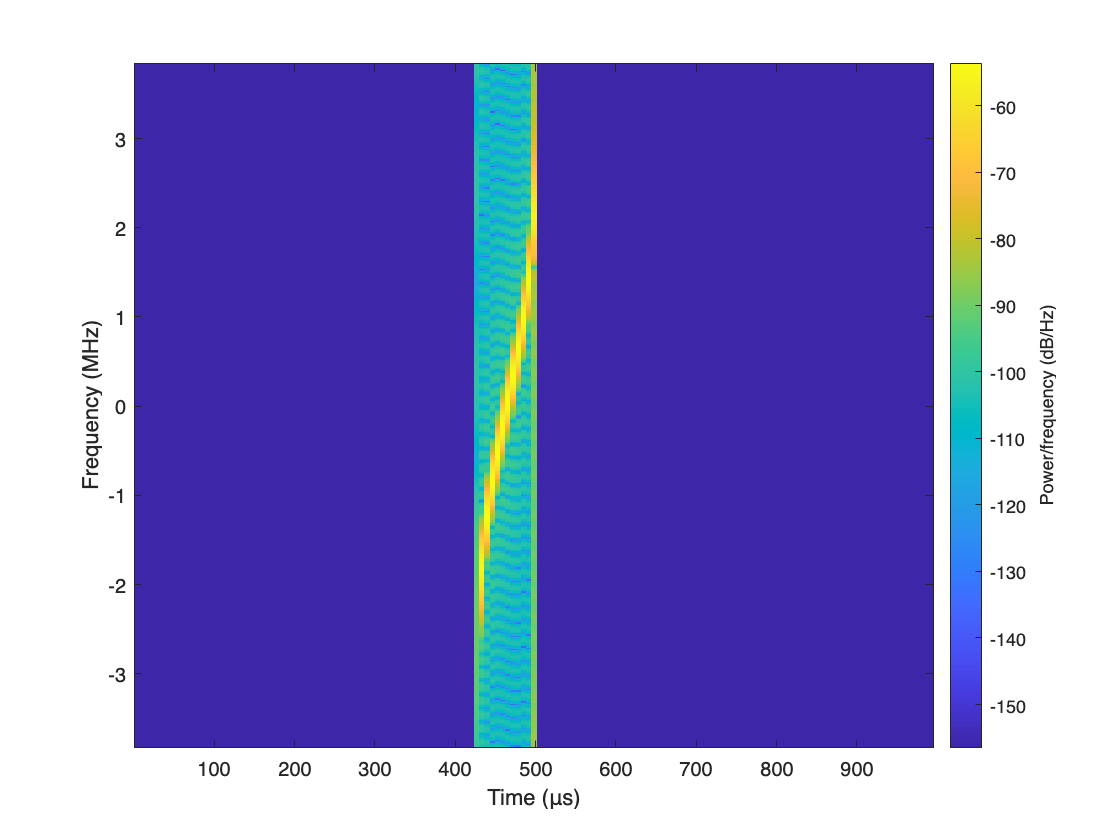



nfft1 = 512;
BW = 5e6;
fs = 10*BW;
fs = 7680000;
w = taylorwin(200,4,-35);
freq = nlfmspec2freq(BW,w);
l = s3;
a = zeros(1,l);
x = complex(a,0);
fm = phased.CustomFMWaveform('SampleRate',fs,'PulseWidth',70e-6,'FrequencyModulation',freq, ...
    'PRF',1e3,'FrequencyOffsetSource','Property','FrequencyOffset',0e6,OutputFormat='Samples',NumSamples=(7680-length(x)));
length(x);
length(fm());

z = [x';fm()];
spectrogram(z,50,0,nfft1,fs,'centered','yaxis') 

disp(['Bandwidth = ',num2str(bandwidth(fm)/1e6),' MHz']);

Bandwidth = 4.9801 MHz


txWaveform + radar

% pulses = step(sRWF);
% pulses(end+1:length(txWaveform))=complex(0);
a = z+txWaveform ;
fprintf("txWaveform + radar")

txWaveform + radar

w = length(a)/200

w = 38.4000

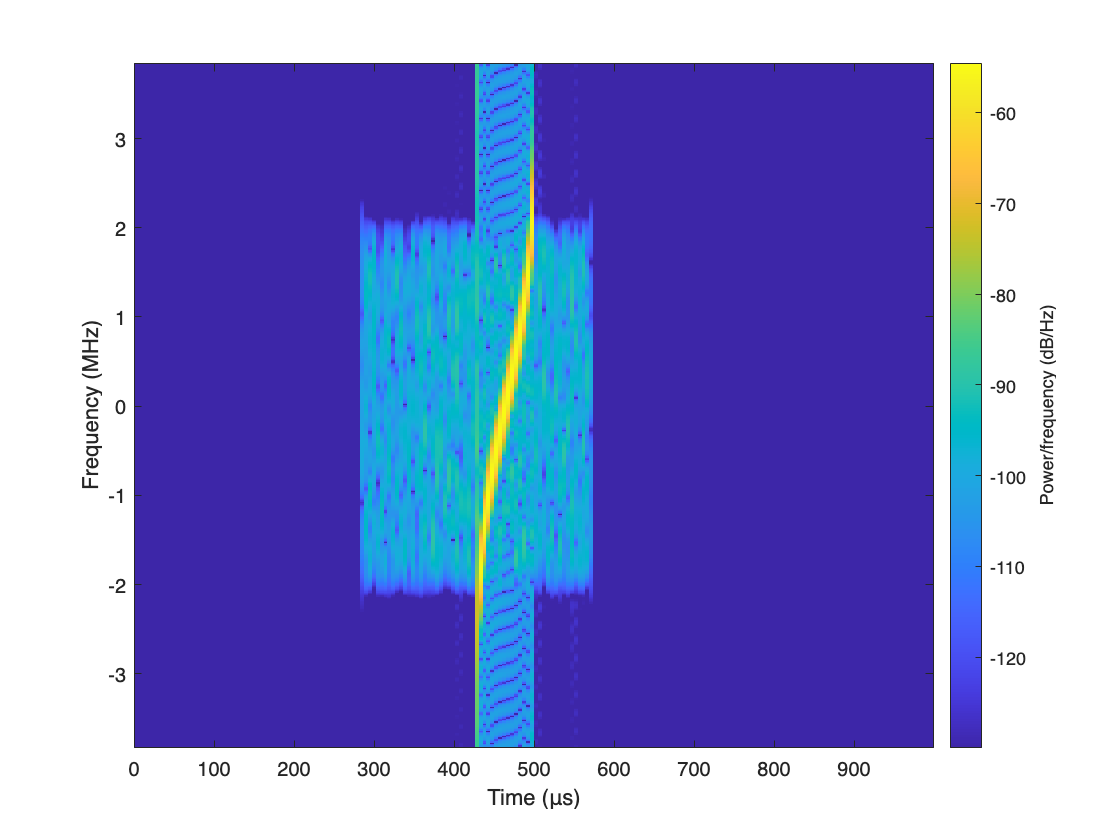

spectrogram(a,w,0,512,'centered',7680000,'yaxis','MinThreshold',-130)

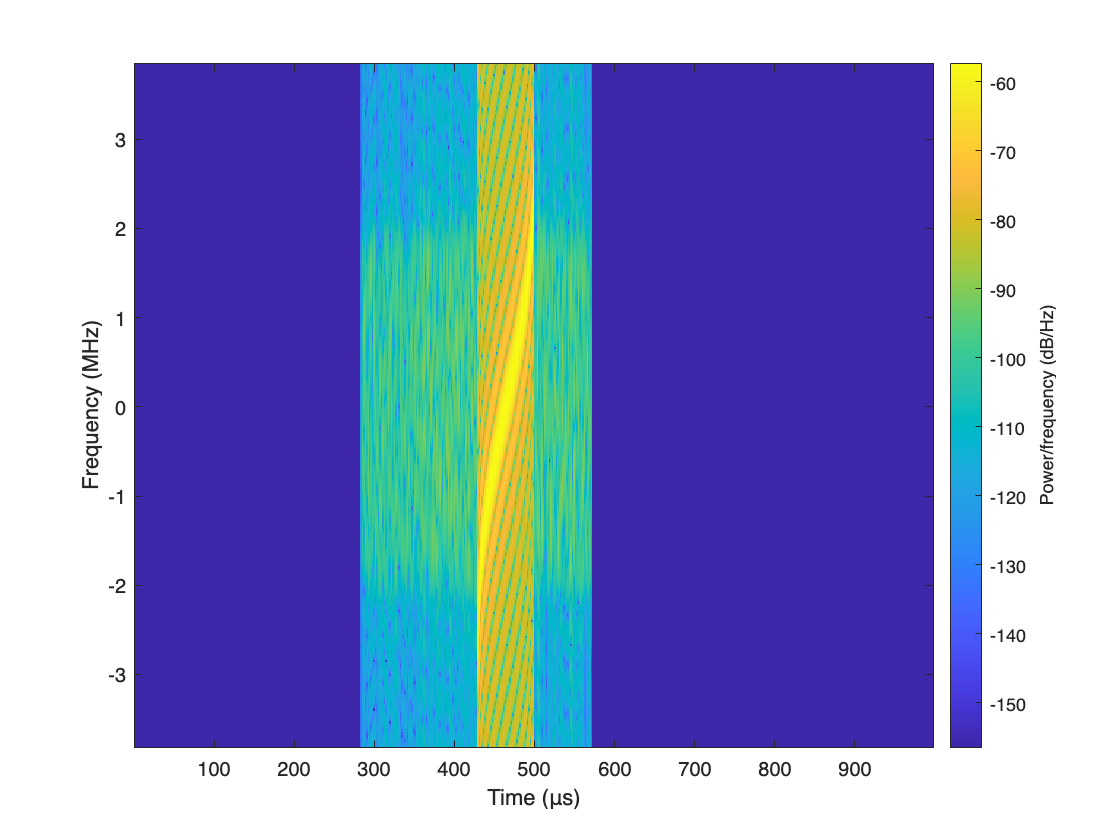

spectrogram(a,symLgths,0,256,fs,'centered','yaxis') 